# **QAM modular**

% ************************************************************************
% Author: CONG LI
% Date Created: 2023
%
% This script is part of a course project for 
% Communication Systems: Theory and Measurement M
% at University of Bologna.
% ************************************************************************
function [t,x,N]=SinusoidalSource_2023(A, f0, T,fs)
Ts=1/fs;
t=0:Ts:T;
x=A*cos(2*pi*f0*t);
N=length(x);
end


close all;
clear all;
clc;

The following code segment define the basic parameter of QAM modular

fs=30000; % sampling frequency
A=1; % amplitude of the modulating in-phase and quadrature sine waves
T=0.5; % duration (sec) of the in-phase and quadrature sine waves
f1=100; % frequency of the modulating sine wave xI in the in-phase path
f2=300; % frequency of the modulating sine wave xQ in the quadrature path
fc=3000; % carrier frequency

## generate (and plot) the modulating sine waves xI and xQ

The following code segment generate the modulating sine waves xI and xQ

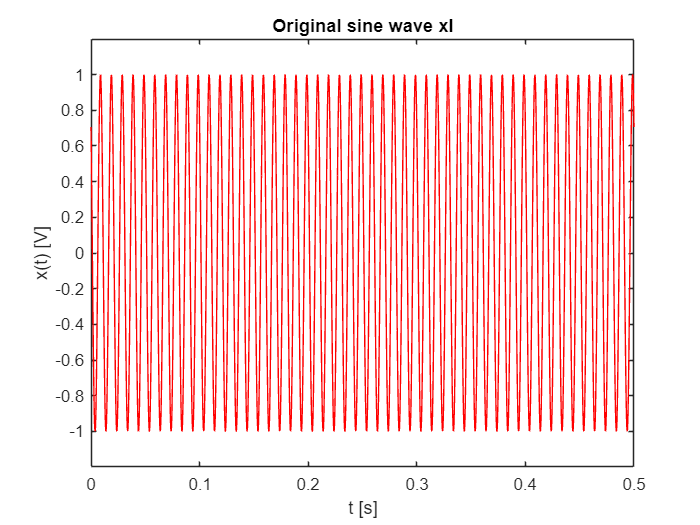

% generate (and plot) the modulating sine waves xI and xQ
% by means of the SinusoidalSource_2023 function
[t,xI,N]=SinusoidalSource_2023(A,f1,T,fs); % generation of the singal
figure
plot(t,xI,'r')
xlabel('t [s]')
ylabel('x(t) [V]')
title('Original sine wave xI')
axis([min(t) max(t) 1.2*min(xI) 1.2*max(xI)])

signal_power=0.5*A^2;
fprintf('XI power [V^2]=%f' , signal_power)

XI power [V^2]=0.500000

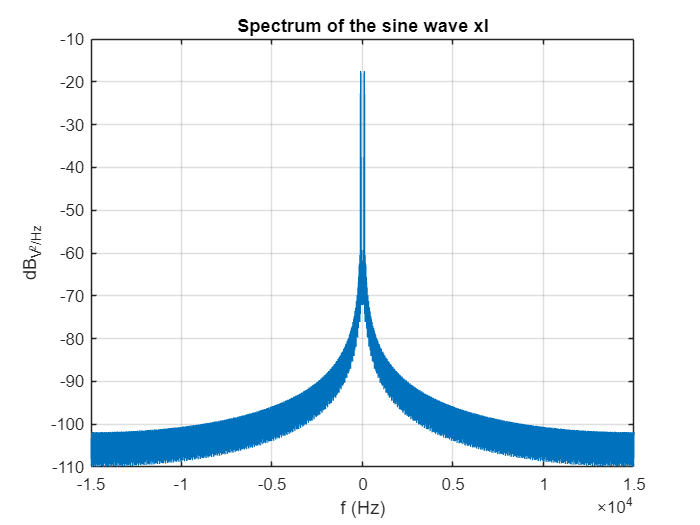

figure
PlotSpectrum(xI,fs);
title('Spectrum of the sine wave xI');

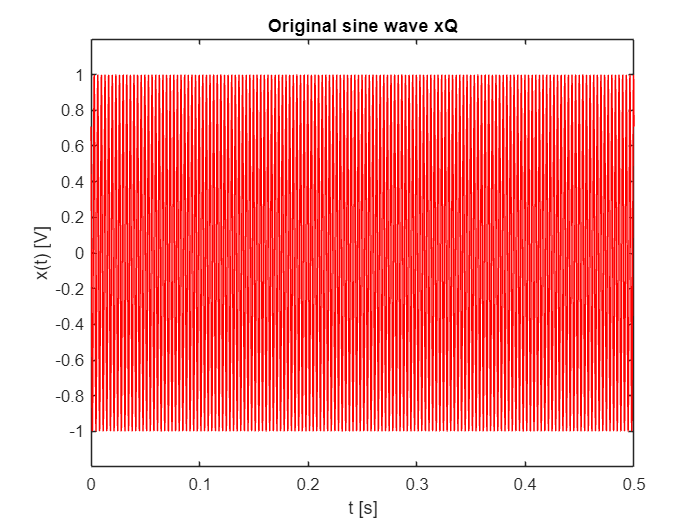

[t,xQ,N]=SinusoidalSource_2023(A,f2,T,fs); % generation of the singal
figure
plot(t,xQ,'r')
xlabel('t [s]')
ylabel('x(t) [V]')
title('Original sine wave xQ')
axis([min(t) max(t) 1.2*min(xQ) 1.2*max(xQ)])

signal_power=0.5*A^2;
fprintf('sinusoid power [V^2]=%f' , signal_power)

sinusoid power [V^2]=0.500000

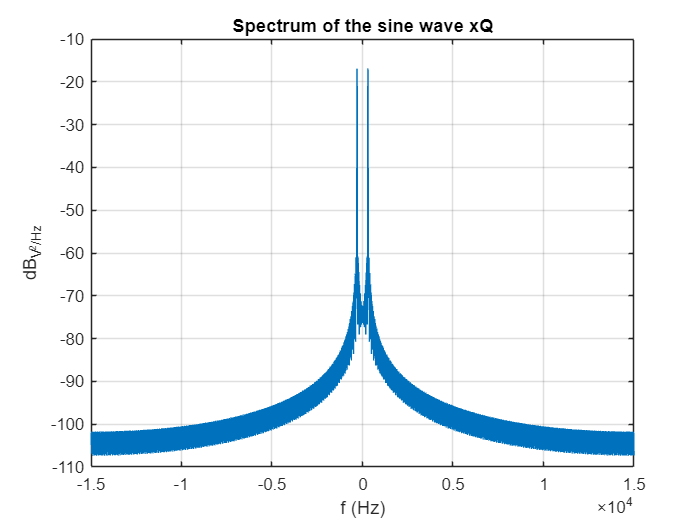

figure
PlotSpectrum(xQ,fs);
title('Spectrum of the sine wave xQ');

## QAM modulation xI and xQ with carrier frequency

QAM modulator combines the multiplication of inputs signal and carrier to modulate signals with carrier frequecy.. 

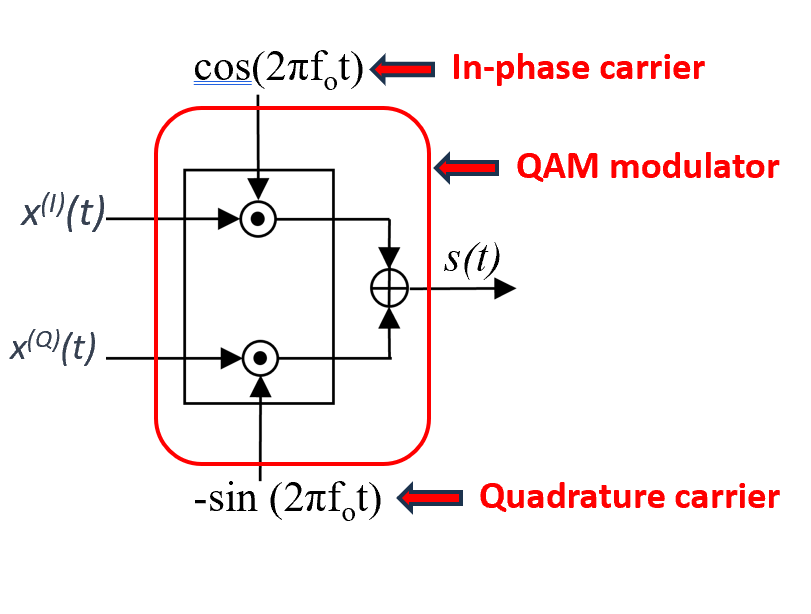

The following code segment generate the QAM modulation signals carrying low-frequency signals to high frequencies and plotting the modulated signal spectrum.

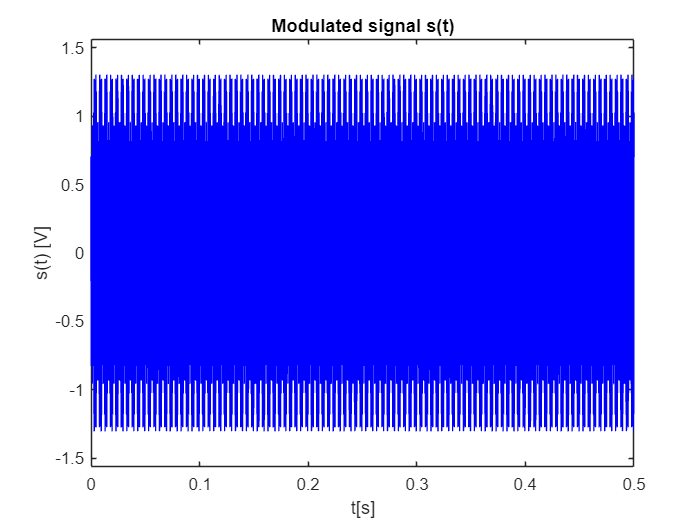

% QAM modulation xI and xQ with carrier frequency
% plot the modulated signal and its spectrum
% (use the function PlotSpectrum_2023(s,fs))
s = ModQAM_2023(xI,xQ,fc,T,fs);
figure
plot(t,s,"b")
xlabel("t[s]")
ylabel("s(t) [V]")
title("Modulated signal s(t)")
axis([min(t) max(t) 1.2*min(s) 1.2*max(s)])

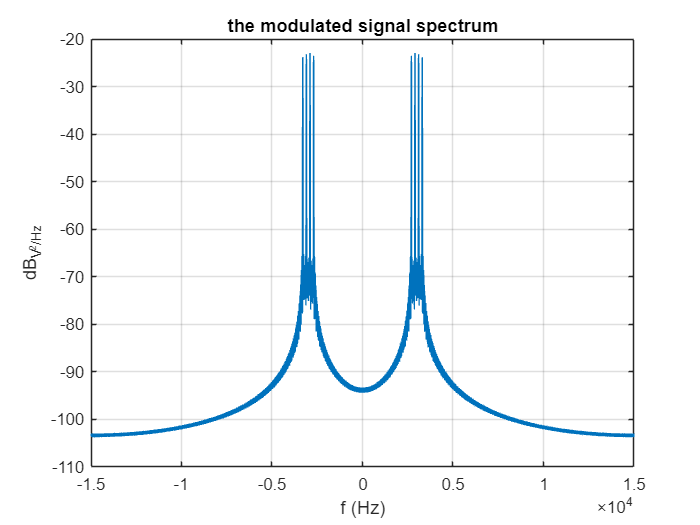


figure
PlotSpectrum_2023(s,fs);
title('the modulated signal spectrum')

This pricure shows the QAM modulated signal sepctrum with input signals 'xI' , 'xQ', the carrier frequency is 3000hz. The signals pectrum is symmetries because the original signal is real signals.

## QAM demodulation

QAM demodulator multiplying inputs signal and carrier, then Convolve of a low-pass filter to demodulate the original signals.

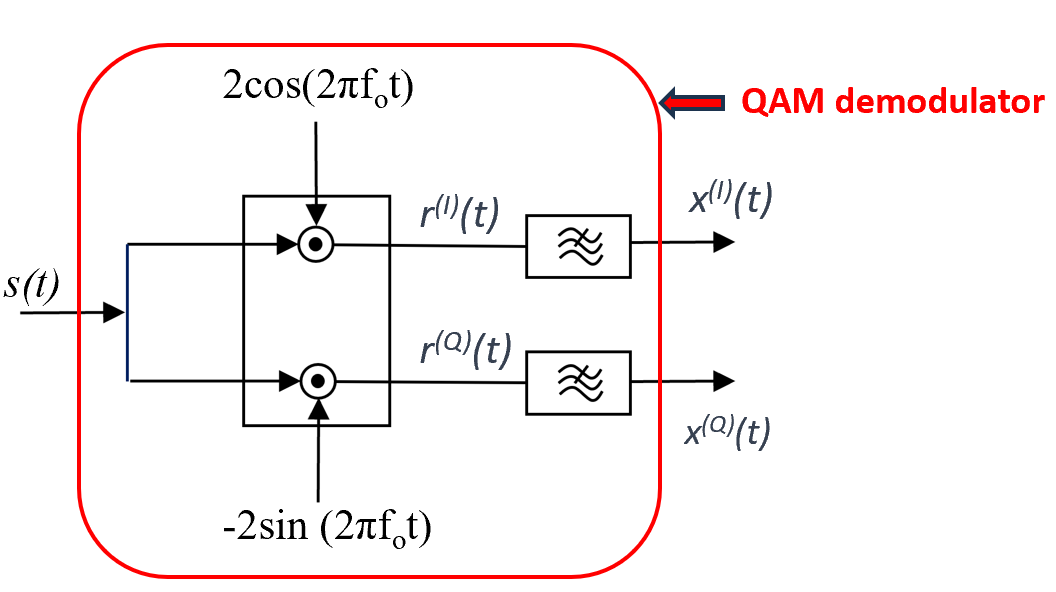

The following code segment demodulate signals from high frequency bands to lower frequencies and plotting. 

% QAM demodulation
% plot the demodulated in-phase and quadrature signals and their spectra
[xi,xq,Delay] = DeModQAM_2023(s,fc,T,fs,0);

Xi =     1.4142    0.2771   -0.2310    0.4567    1.3290    1.2586    0.4246   -0.0852    0.2746    0.9432    1.0893    0.6003    0.0788    0.0753    0.5291    0.9080    0.7772    0.2435   -0.1233    0.1169    0.7167    0.9275    0.3913   -0.3031   -0.2637    0.5176    1.0256    0.5061   -0.4484   -0.5868    0.3129    1.0505    0.5750   -0.5465   -0.8323    0.1047    0.9880    0.5895   -0.5895   -0.9880   -0.1047    0.8323    0.5465   -0.5750   -1.0505   -0.3129    0.5868    0.4484   -0.5061   -1.0256


Xq =          0   -0.2013    0.7109    1.4055    0.9656   -0.0000   -0.3085    0.2623    0.8452    0.6853   -0.0000   -0.4361   -0.2424    0.2317    0.3844    0.0000   -0.5647   -0.7494   -0.3793    0.0849   -0.0000   -0.6739   -1.2043   -0.9330   -0.1916    0.0000   -0.7452   -1.5576   -1.3800   -0.4263    0.0000   -0.7632   -1.7696   -1.6819   -0.6047    0.0000   -0.7178   -1.8143   -1.8143   -0.7178    0.0000   -0.6047   -1.6819   -1.7696   -0.7632   -0.0000   -0.4263   -1.3800   -1.5576   -0.7452


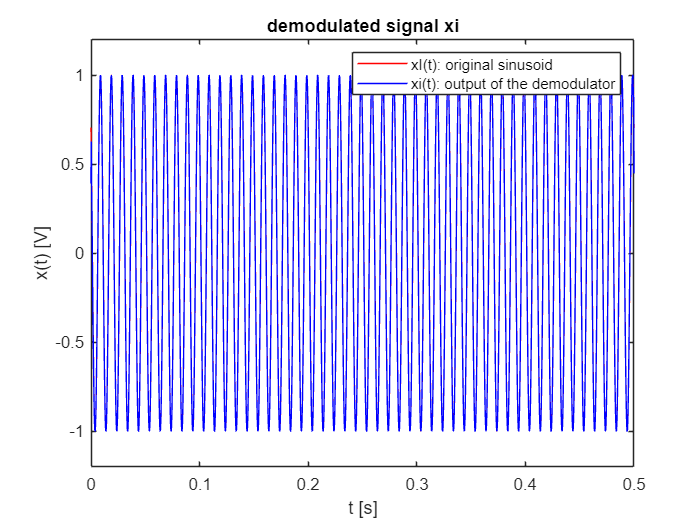

figure
plot(t,xI,'r')
hold on
plot(t,xi,'b')
legend ('xI(t): original sinusoid','xi(t): output of the demodulator')

xlabel('t [s]')
ylabel('x(t) [V]')
title('demodulated signal xi')
axis([min(t) max(t) 1.2*min(xi) 1.2*max(xi)])

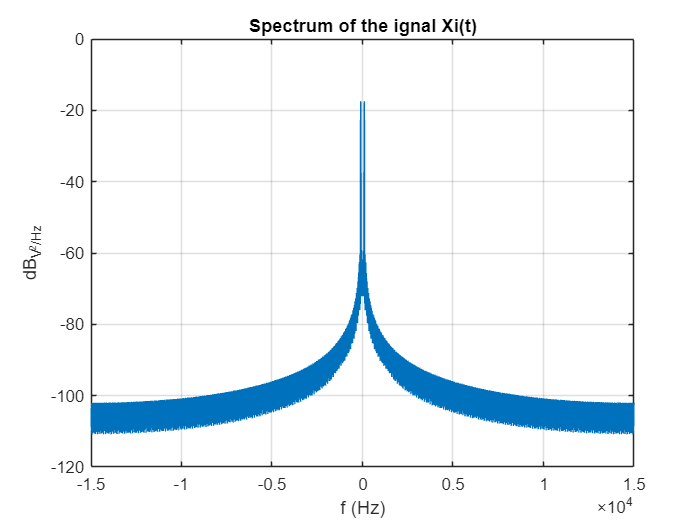

figure
PlotSpectrum(xi,fs);
title('Spectrum of the ignal Xi(t)');

Output signal xI can be demodulated by demodulation function. It is as same as the original xI signal in amplitude, frequency and phase.

signal_power=0.5*A^2;
fprintf('sinusoid power [V^2]=%f' , signal_power)

sinusoid power [V^2]=0.500000

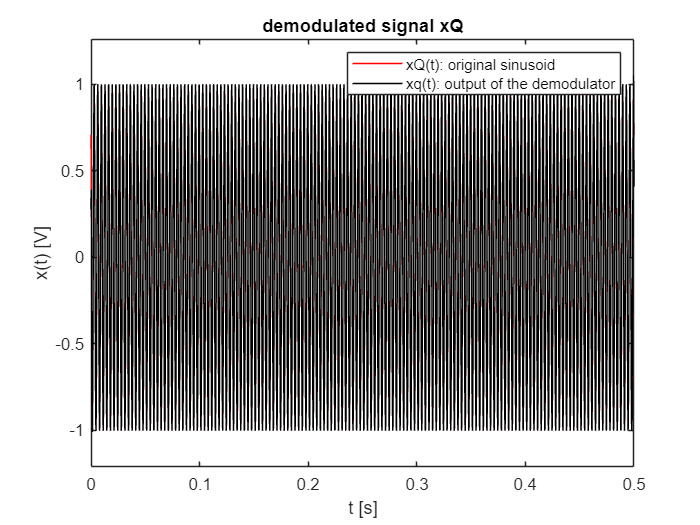


figure
plot(t,xQ,'r')
hold on
plot(t,xq,'k')
legend ('xQ(t): original sinusoid','xq(t): output of the demodulator')
xlabel('t [s]')
ylabel('x(t) [V]')
title('demodulated signal xQ')
axis([min(t) max(t) 1.2*min(xq) 1.2*max(xq)])

This picture gives us the information of the comparsion about original xq signal and demodulated signal xq. The conculsion is same with xI signals.

signal_power=0.5*A^2;
fprintf('sinusoid power [V^2]=%f' , signal_power)

sinusoid power [V^2]=0.500000

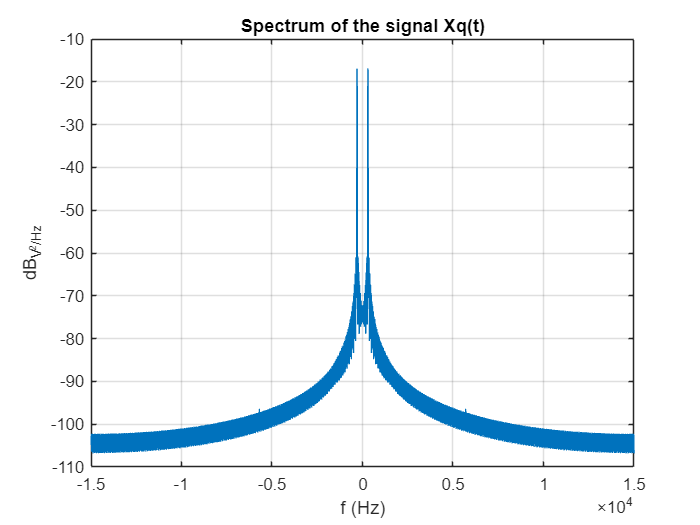

figure
PlotSpectrum(xq,fs);
title('Spectrum of the signal Xq(t)');

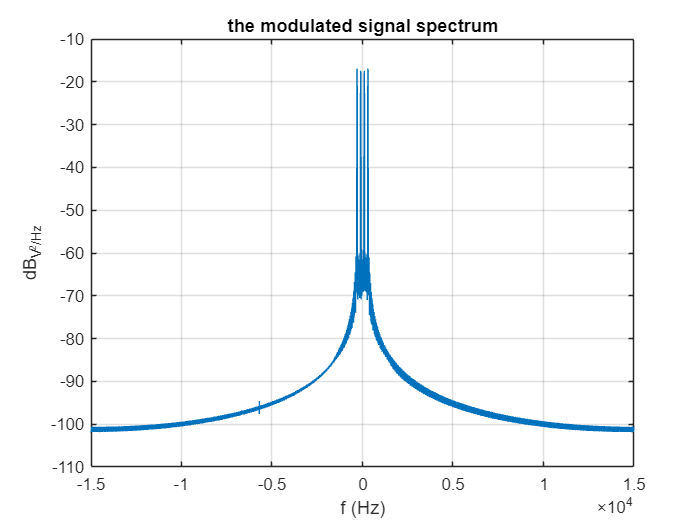

s_demod=xi+xq*j;
figure
PlotSpectrum_2023(s_demod,fs);
title('the modulated signal spectrum')

figure
plot(t,s_demod,"b")

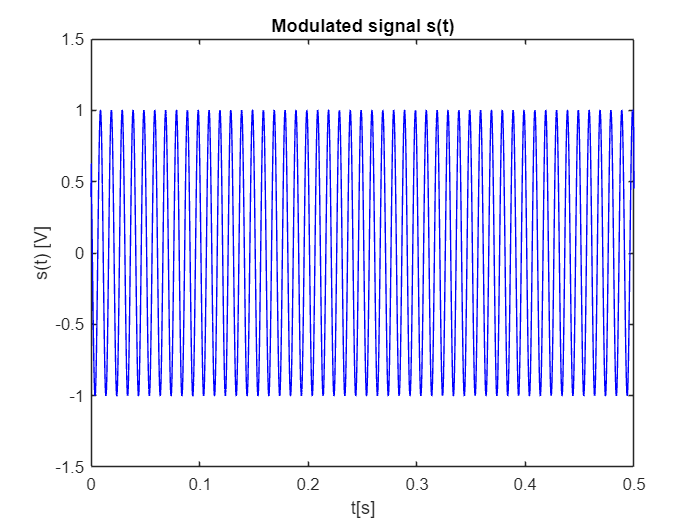

xlabel("t[s]")
ylabel("s(t) [V]")
title("Demodulated signal s(t)")

This picture gives the information about spectrum of  demodulated signals s = xi+xq, comparing with the spectrum of modulated signals it shifted 3000hz in frequency domian. So the modulation is a process of moving signals from low frequency to high frequency for transmissoin by production a sin or cos function with carrier frequency. The demodulation is a process of moving signals from high frequency to low frequency for extracting information by convex opeartion.The whole process are linera time invariant and do not change any information.

** If the offset is not zero and it is  pi/4**

** If the offset is not zero and it is  pi/2**